## Dados Coletados

Primeiro precisamos importar os dados coletados:

data = readtable("scripts/data/calibration_data.csv")

data = 11×2 table
    Force    Voltage
    _____    _______

       0          0 
     0.5      0.004 
       1      0.007 
     1.5       0.01 
       2      0.012 
     2.5      0.014 
       3      0.015 
     3.5      0.016 
       4      0.017 
     4.5      0.017 
       5      0.018 


clf;
subplot(1, 2, 1);
scatter(data.Force, data.Voltage, 'filled');
title('Dados Coletados');
xlabel('Força (N)'), ylabel('Tensão (V)');
box on;

subplot(1, 2, 2);
fitted = fit(data.Force, data.Voltage, 'poly2')

fitted =      Linear model Poly2:
     fitted(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =  -0.0007786  (-0.0009021, -0.000655)
       p2 =    0.007293  (0.006651, 0.007934)
       p3 =   0.0003986  (-0.0002907, 0.001088)

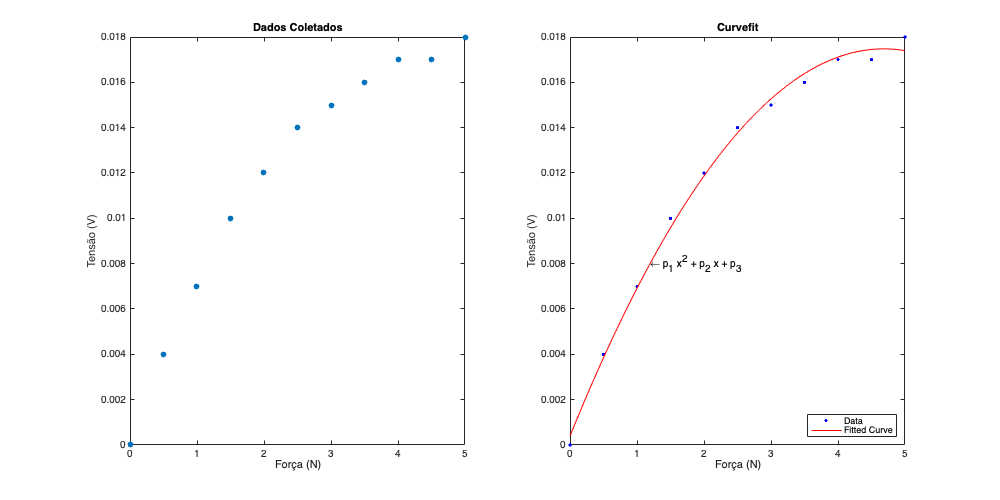

plot(fitted, data.Force, data.Voltage);
legend('Data', 'Fitted Curve', 'Location','southeast');
text(1.2, 0.008, '\leftarrow p_1 x^2 + p_2 x + p_3');
title('Curvefit');
xlabel('Força (N)'), ylabel('Tensão (V)');


fig=gcf;
fig.Position(3:4)=[1000,500];

saveas(gcf, 'curve_fitting.png');